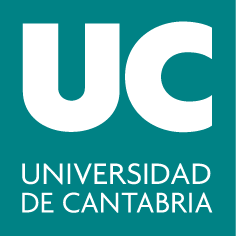

#### ***Grado en Ingeniería ****de Tecnologías de Telecomunicación*

## **G283: Cálculo II**

# **Práctica 13: EDOs de primer orden. Isoclinas y campos de direcciones**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### Objetivos	

- Utilizar representaciones gráficas para profundizar en el estudio de las soluciones de una ecuación diferencial de primer orden.

- Representar las isoclinas de una ecuación diferencial ordinaria de primer orden como apoyo para trazar un campo de direcciones.

- Representar el campo de direcciones de una ecuación diferencial ordinaria de primer orden y entender su significado. 	

### Resumen teórico

*Isoclina*:  Dada una ecuación diferencial ordinaria $y'=f(x,y)$, se llama  isoclina al lugar geométrico de los puntos del plano donde la pendiente de las curvas solución es constante, siendo su ecuación $f(x,y)=C$

*Campo de direcciones:* Dada una ecuación diferencial ordinaria $y'=f(x,y)$, se llama  campo de direcciones a la representación gráfica de una muestra de pequeños segmentos de rectas tangentes a las curvas solución, dibujados sobre los puntos de corte de éstas con las isoclinas.

### Comandos útiles

**Comando para definir una función en línea**

- `F=@(x,y) eq `Con este comando se definen funciones en línea evaluables, de una o de varias variables.

F=@(x,y) x.*y
valor=F(2,4)

**Representación de una función en forma implícita**

- `ezplot(F, [xmin, xmax]) `Para representar la función implícita definida por la ecuación $f(x,y)=C$ en la región del plano $[a, b] \times [c,d]$.  $f(x,y)$ puede ser un string o una función en línea (función `@`).

figure(1)
F=@(x,y) x.^2+y.^2-4;
ezplot(F,[-2,2]) % utilizando una función en línea
ezplot('x^2+y^2-4=0',[-2,2]) %utilizando un string

**   Comando para resolver ecuaciones diferenciales y problemas de valor inicial     **

- `syms y(x)`: crea la variable simbólica `y` que depende de `x`.

- `diff(var, n)`:  Para denotar la derivada de la variable simbólica `var` de orden `n`.

- `dsolve(eq, cond)`: Para resolver ecuaciones diferenciales de forma simbólica. Si se especifica la condición inicial `cond`, se obtiene la solución particular del problema de valor inicial.

Ejemplos:

syms y(x)
solEDO=dsolve(diff(y,x) ==-3*x) 

Si se añade una condición inicial se obtiene la solución particular al problema de valor inicial:

solPVI=dsolve(diff(y,x) ==-3*x, y(0)==1) 

Otra forma de hacerlo es usando cadenas de caracteres en lugar de variable simbólica, pero no se recomienda pues estará obsoleto en futuras versiones: 

dsolve('Dy=-3*x', 'x') % hay que especificar la variable independiente, por defecto t

###  Ejercicios resueltos

**1. **Considera la ecuacion diferencial ordinaria: $y'=x^2+2y$        	

Crea tres figuras, en el cuadrado $[-2,2]\times[-2,2]$, representando en todas ellas una muestra del campo de direcciones. 

En la figura 1, representa además las isoclinas de pendientes $y'= -4:1:6$

En la figura 2 representa las soluciones particulares que pasan por los puntos $P(1,1), Q(-1/3, -1), R(-1,1), S(1,-1)$

En la figura 3, representa las líneas que separan las regiones del plano donde las soluciones particulares son crecientes-decrecientes y cóncavas-convexas.

La ecuación de las isoclinas es:


$$y'=m \rightarrow x^2+2y=m \rightarrow y=\frac{m-x^2}{2}$$


El estudio del crecimiento y la concavidad:

Crecientes si $y> \frac{-x^2}{2}$    decrecientes si $y< \frac{-x^2}{2}$

Cóncavas hacia arriba si $y> \frac{-x^2-x}{2}$   cóncavas hacia abajo si $y< \frac{-x^2-x}{2}$

figure(2)
%Fija el marco de la ventana [-2,2]x[-2,2]
axis([-2, 2, -2, 2])
hold on
%Dibuja el eje OX y el eje OY
plot([-2,2],[0,0],'k',[0,0],[-2,2],'k')
%Dibuja las isoclinas en el bucle
xv=-2:0.1:2; %dominio x de las isoclinas (hipérbolas)
%Vector con los valores de las pendientes de las isoclinas
for m=-4:1:6
yv=(m-xv.^2)./2; % ordenada de las isoclinas
plot(xv,yv,'b') %dibujo de las isoclinas en azul
end
%Dibuja el campo de direcciones representado por vectores de la forma (1,y’)
%definición de la derivada en cualquier punto (x,y)
f=@(x,y) x.^2+2*y;
%Rejilla de puntos para dibujar los vectores tangentes a las
%curvas solución que pasan por dichos puntos
[X,Y]=meshgrid(-2:0.3:2);
U=ones(size(X)); %primera componente del vector tangente
V=f(X,Y); %segunda componente del vector tangente
%Dibuja los vectores del campo de direcciones negro
h=quiver(X,Y,U,V,'k');
set(h,'ShowArrowHead','off') %quita la flecha de los vectores
title('isoclinas de y´=x^2+2y, campo de direcciones')
hold off
figure(3)
axis([-2, 2, -2, 2])
hold on
plot([-2,2],[0,0],'k',[0,0],[-2,2],'k')
%Incluir el campo de direcciones como antes
h=quiver(X,Y,U,V,'k');
set(h,'ShowArrowHead','off') %quita la flecha de los vectores
%Calcula la solución particular que pasa por el punto P(1,1)
syms y(x)
yp=dsolve(diff(y,x,1)==x^2+2*y,y(1)==1)
h1=ezplot(yp,[-2,2,-2,2]); %dibuja la solución particular en rojo
set(h1,'Color','r')
plot(1,1,'om')
%Calcula la solución particular que pasa por el punto Q(-1/3,-1)
yp=dsolve(diff(y,x,1)==x^2+2*y,y(-1/3)==-1)
h2=ezplot(yp,[-2,2,-2,2]); %dibuja la solución particular en rojo
set(h2,'Color','r')
plot(-1/3,-1,'om')
%Calcula la solución particular que pasa por el punto R(-1,1)
yp=dsolve(diff(y,x,1)==x^2+2*y,y(-1)==1)
h3=ezplot(yp,[-2,2,-2,2]); %dibuja la solución particular en rojo
set(h3,'Color','r')
plot(-1,1,'om')
%Calcula la solución particular que pasa por el punto S(1,-1)
yp=dsolve(diff(y,x,1)==x^2+2*y,y(1)==-1)
h4=ezplot(yp,[-2,2,-2,2]); %dibuja la solución particular en rojo
set(h4,'Color','r')
plot(1,-1,'om')
title('Campo de direcciones de y´=x^2+2y, soluciones particulares')
hold off
figure(4)
axis([-2, 2, -2, 2])
hold on
plot([-2,2],[0,0],'k',[0,0],[-2,2],'k')
%Incluir el campo de direcciones como antes
h=quiver(X,Y,U,V,'k');
set(h,'ShowArrowHead','off') %quita la flecha de los vectores
%Dibuja la curva y=-x^2/2, donde cambia el crecimiento, en azul
yv1=-xv.^2./2;
plot(xv,yv1,'b')
%Dibuja la curva y=(-x^2-x)/2, donde cambia la concavidad, en rojo
yv2=(-xv.^2-xv)./2;
plot(xv,yv2,'r')
legend('y=-x^2/2, cambia el crecimiento','y=(-x^2-x)/2, cambia la concavidad')
title('Campo de direcciones y estudio del crecimiento y la concavidad')
hold off

**2. **Considera la ecuacion diferencial ordinaria: $y'=-x^2+y$        	

Crea tres figuras, en el cuadrado $[-2,2]\times[-2,2]$, representando en todas ellas una muestra del campo de direcciones. 

En la figura 1, representa además las isoclinas de pendientes $y'= -2:0.8:2$

En la figura 2 representa las soluciones particulares que pasan por los puntos $P(-1,0), Q(-1/2, 1), R(1, 3/2), S(1,1/2)$

En la figura 3, representa las líneas que separan las regiones del plano donde las soluciones particulares son crecientes-decrecientes y cóncavas-convexas.

La ecuación de las isoclinas es:


$$y'=m \rightarrow -x^2+y=m \rightarrow y=m+x^2}$$


El estudio del crecimiento y la concavidad:

Crecientes si $y> x^2$    decrecientes si $y< x^2$

Cóncavas hacia arriba si $y> x^2+2x$   cóncavas hacia abajo si $y< x^2+2x$

figure(5)
%Fija el marco de la ventana [-2,2]x[-2,2]
axis([-2, 2, -2, 2])
hold on
%Dibuja el eje OX y el eje OY
plot([-2,2],[0,0],'k',[0,0],[-2,2],'k')
%Dibuja las isoclinas en el bucle
xv=-2:0.1:2; %dominio x de las isoclinas (hipérbolas)
%Vector con los valores de las pendientes de las isoclinas
for m=-2:0.8:2;
yv=m+xv.^2; % ordenada de las isoclinas
plot(xv,yv,'b') %dibujo de las isoclinas en azul
end
%Dibuja el campo de direcciones representado por vectores de la
%forma (1,y’)
%definición de la derivada en cualquier punto (x,y)
f=@(x,y) -x.^2+y;
%Rejilla de puntos para dibujar los vectores tangentes a las
%curvas solución que pasan por dichos puntos
[X,Y]=meshgrid(-2:0.3:2);
U=ones(size(X)); %primera componente del vector tangente
V=f(X,Y); %segunda componente del vector tangente
%Dibuja los vectores del campo de direcciones negro
h=quiver(X,Y,U,V,'k');
set(h,'ShowArrowHead','off') %quita la flecha de los vectores
title('isoclinas de y´=-x^2+y, campo de direcciones')
hold off
figure(6)
axis([-2, 2, -2, 2])
hold on
plot([-2,2],[0,0],'k',[0,0],[-2,2],'k')
%Incluir el campo de direcciones anterior
h=quiver(X,Y,U,V,'k');
set(h,'ShowArrowHead','off') %quita la flecha de los vectores
%Calcula la solución particular que pasa por el punto P(-1,0)
yp=dsolve(diff(y,x,1)==-x^2+y,y(-1)==0)
h1=ezplot(yp,[-2,2,-2,2]); %dibuja la solución particular en rojo
set(h1,'Color','r')
plot(-1,0,'om')
%Calcula la solución particular que pasa por el punto Q(-1/2,1)
yp=dsolve(diff(y,x,1)==-x^2+y,y(-1/2)==1)
h2=ezplot(yp,[-2,2,-2,2]); %dibuja la solución particular en rojo
set(h2,'Color','r')
plot(-1/2,1,'om')
%Calcula la solución particular que pasa por el punto R(1,3/2)
yp=dsolve(diff(y,x,1)==-x^2+y,y(1)==3/2)
h3=ezplot(yp,[-2,2,-2,2]); %dibuja la solución particular en rojo
set(h3,'Color','r')
plot(1,3/2,'om')
%Calcula la solución particular que pasa por el punto S(1,1/2)
yp=dsolve(diff(y,x,1)==-x^2+y,y(1)==1/2)
h4=ezplot(yp,[-2,2,-2,2]); %dibuja la solución particular en rojo
set(h4,'Color','r')
plot(1,1/2,'om')
title('Campo de direcciones de y´=-x^2+y, soluciones particulares')
hold off
figure(7)
axis([-2, 2, -2, 2])
hold on
plot([-2,2],[0,0],'k',[0,0],[-2,2],'k')
%Incluir el campo de direcciones anterior
h=quiver(X,Y,U,V,'k');
set(h,'ShowArrowHead','off') %quita la flecha de los vectores
%Dibuja la curva y=x^2, donde cambia el crecimiento, en azul
yv1=xv.^2;
plot(xv,yv1,'b')
%Dibuja la curva y=x^2+2x, donde cambia la concavidad, en rojo
yv2=xv.^2+2*xv;
plot(xv,yv2,'r')
legend('y=x^2, cambia el crecimiento','y=x^2+2x, cambia la concavidad')
title('Campo de direcciones y estudio del crecimiento y la concavidad')
hold off